# SC42025 Filtering & Identification

**MATLAB EXERCISE HW3**

**Instructions: Fill in the live script with your code and answers. Then export the live script as a pdf (in the 'Live Editor tab', click on the arrow under 'Save' and then 'Export to pdf').**

**General Hints:**

- The live script is devided in several sections. You can **execute the sections seperately.**

- To reduce the runtime, you can comment the test-functions. Make sure, that all test-functions are uncommented when you export the live script and that their output appears on the pdf. **Missing test-function output will be treated as "wrong" regardless of the implementation.**

- Please **do not change given variable names or variables or any other code that you are asked to not change**. Otherwise the functionality of the live script and the testfunctions cannot be guaranteed.

- If you decide to implement your functions in seperate files, make sure to copy the code to the bottom of the script before you export it.** Missing code will be treated as "wrong" regardless of the result of the testfunction. **

- **Please read the cheat sheet carefully.**

Consider the following Output Error system:


$$y(k) = \frac{b_2q^{-2}+b_3q^{-3}+b_4q^{-4}}{1+a_1q^{-1}+a_2q^{-2}+a_3q^{-3}+a_4q^{-4}}u(k) + e(k) .$$


close all; clear; clc; 
addpath('./function_folder')

load iodata.mat

## **Questions **

**a)  **Parameterize the system using the observable canonical form (according to the lecture slides!).

*Answer**: *


$$ y(k) = H^{-1}\hat G u(k) + [1- H ^{-1}]e(k) \\
H = 1 \Rightarrow H^{-1} = 1 \Rightarrow \hat G = G, \, \hat H = 0 \\
$$


As such the K matrix is 0, and the prediction is only based on u(k).


$$A = 
\left[
\matrix{ -a_1 & 1 & 0 & 0 \cr
-a_2 & 0 & 1 & 0 \cr
-a_3 & 0 & 0 & 1 \cr
-a_4 & 0 & 0 & 0 \cr
} \right] \qquad 
B = \left[
\matrix{ 0 \cr b_2 \cr b_3 \cr b_4 \cr 
}
\right] \qquad
x_0 = \left[
\matrix{ x_{1, 0} \cr x_{2, 0} \cr x_{3, 0} \cr  x_{4, 0} \cr
}
\right] \\
C = \left[
\matrix{ 1 & 0 & 0 & 0
} \right] \qquad
D = \left[
\matrix{ 0 } \right] \qquad \\

\theta_A = \left[
\matrix{ -a_1 & -a_2 & -a_3 & -a_4 } \right] \\
\theta_B = \left[
\matrix{  b_2 & b_3 & b_4 } \right] \qquad
\theta_{x_0} = \left[
\matrix{ x_{1, 0} & x_{2, 0} & x_{3, 0} &  x_{4, 0} } \right] \qquad

$$


**b) **How many parameters do we have in part (a) ($\theta\in\mathbb{R}^p$)*?* Represent as $\theta=\pmatrix{
    \theta_A\cr \theta_B \cr \theta_{x_0}}$.

*Answer**: From the above equations 11 unknowns can be counted.*

**c)  **We are now going to implement a  Prediction Error method ($\texttt{pem.m}$) for the Output Error system. We will do this in the following four steps:

I. Derive expressions for $\frac{\partial \bar{A} \left(\theta \right)}{\partial \theta_p^{\left(i\right)} }$, $\frac{\partial \bar{B} \left(\theta \right)}{\partial \theta_p^{\left(i\right)} }$, $\frac{\partial K\left(\theta \right)}{\partial \theta_p^{\left(i\right)} }$, $\frac{\partial C\left(\theta \right)}{\partial \theta_p^{\left(i\right)} }$, $\frac{\partial D\left(\theta \right)}{\partial \theta_p^{\left(i\right)} }$, $\frac{\partial x_0 \left(\theta \right)}{\partial \theta_p^{\left(i\right)} }$ $(\textrm{for all\,} p)$.

$\frac{\partial \bar{A} \left(\theta \right)}{\partial \theta_p^{\left(i\right)} }$ = $\left(
\matrix{ 1 & 0 & 0 &  0 \cr 0 & 0 & 0 &  0 \cr  0 & 0 & 0 &  0 \cr  0 & 0 & 0 &  0 \cr }
\quad \matrix{ 0 & 0 & 0 &  0 \cr 1 & 0 & 0 &  0 \cr  0 & 0 & 0 &  0 \cr  0 & 0 & 0 &  0 \cr }
\quad \matrix{ 0 & 0 & 0 &  0 \cr 0 & 0 & 0 &  0 \cr  1 & 0 & 0 &  0 \cr  0 & 0 & 0 &  0 \cr }
\quad \matrix{ 0 & 0 & 0 &  0 \cr 0 & 0 & 0 &  0 \cr  0 & 0 & 0 &  0 \cr  1 & 0 & 0 &  0 \cr }
\dots
\right)$

 $\frac{\partial \bar{B} \left(\theta \right)}{\partial \theta_p^{\left(i\right)} }$ = $\left(
\matrix{ 0  \cr  0 \cr 0   \cr 0 }
\quad \matrix{ 0  \cr  0 \cr 0   \cr 0 }
\quad \matrix{ 0  \cr  0 \cr 0   \cr 0 }
\quad \matrix{ 0  \cr  0 \cr 0   \cr 0 }
\quad \matrix{ 0  \cr  0 \cr 0   \cr 0 \cr}
\quad \matrix{ 0  \cr 1  \cr  0 \cr  0  \cr }
\quad \matrix{ 0  \cr 0  \cr  1 \cr  0  \cr }
\quad \matrix{ 0  \cr 0  \cr  0 \cr  1  \cr }
\quad \matrix{ 0  \cr  0 \cr 0   \cr 0 }
\quad \matrix{ 0  \cr  0 \cr 0   \cr 0 }
\quad \matrix{ 0  \cr  0 \cr 0   \cr 0 }
\quad \matrix{ 0  \cr  0 \cr 0   \cr 0 }
\right)$

 $\frac{\partial K\left(\theta \right)}{\partial \theta_p^{\left(i\right)} }$=zeros(4, p)

 $\frac{\partial C\left(\theta \right)}{\partial \theta_p^{\left(i\right)} }$=zeros(1, 4*p)

$\frac{\partial D\left(\theta \right)}{\partial \theta_p^{\left(i\right)} }$ = zeros(1, p)

$\frac{\partial x_0 \left(\theta \right)}{\partial \theta_p^{\left(i\right)} }$ = $\left( \matrix{ 0  \cr  0 \cr 0   \cr 0 }
\quad \matrix{ 0  \cr  0 \cr 0   \cr 0 }
\quad \matrix{ 0  \cr  0 \cr 0   \cr 0 }
\quad \matrix{ 0  \cr  0 \cr 0   \cr 0 }
\quad \matrix{ 0  \cr  0 \cr 0   \cr 0 }
\quad \matrix{ 0  \cr  0 \cr 0   \cr 0 }
\quad \matrix{ 0  \cr  0 \cr 0   \cr 0 }
\quad \matrix{ 1  \cr  0 \cr 0   \cr 0 \cr}
\quad \matrix{ 0  \cr 1  \cr  0 \cr  0  \cr }
\quad \matrix{ 0  \cr 0  \cr  1 \cr  0  \cr }
\quad \matrix{ 0  \cr 0  \cr  0 \cr  1  \cr }
\right)$

II.   on the result in part (a), implement a MATLAB function that computes the state-space matrices from the parameter vector $\theta$. (*Look at* $\texttt{theta2matrices.m}$ *in the provided template*).

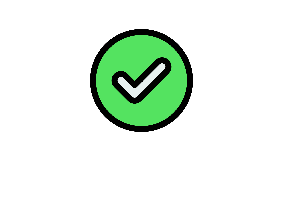

Nice job! theta2matrices is correct!


[~] = test_theta2matrices;

III. Write a function $\texttt{simsystem.m}$ that simulates a dynamic system given any input vector $u$ and matrices $A,B,C,D$, as well as initial condition $x(0)$.

Nice job! simsystem is correct!


[~] = test_simsystem;

IV. 

- Implement a function $\texttt{jacobian.m}$ that calculates the Jacobian vector.

Nice job! jacobian is correct!


[~] = test_jacobian;

- Implement a function $\texttt{hessian.m}$ that calculates the approximated Hessian matrix.

Nice job! hessian is correct!


[~] = test_hessian;

**Note**: The convergence loop for the regularized Gauss-Newton algorithm is already implemented in the $\texttt{pem.m}$ function. There is no reason to edit this.

**d) **Choose two different initial guesses for $\theta$. For each guess, train two models such that the first model is obtained from the first 500 samples and the second one is obtained from the first 1000 samples (from the given iodata.mat). Then, apply all four identified models on **the validation set** and plot the predicted output of all models (only for the validation set) in one figure. Add the numerical values of the VAF and the RMSE to the legend of this figures. (Do not forget to label the models properly!)

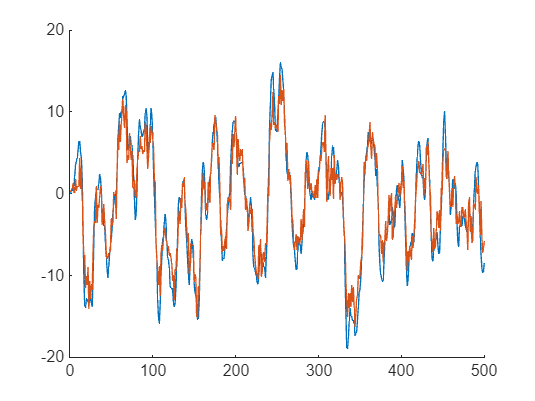

% split data

ut1 = u(1:500);            % input for train-set 1
ut2 = u(1:1000);           % input for train-set 2
uv = u(1001:end);          % input for validation-set

yt1 = ymeas(1:500);        % output for train-set 1
yt2 = ymeas(1:1000);       % output for train-set 2
yv = ymeas(1001:end);      % output for validation-set



theta1 = [1, 0, -0.1, 0, 1, 1, 1, 0, 0.5, 0, 0.5]';
y_ref = yt1;
u_ref = ut1;
% theta = [0 0 0 0 0 0 0 0 0 0 0 ]';
[A, B, C, D, x0] = theta2matrices(theta1);
[y_sim, x_sim] = simsystem(A, B, C, D, x0, u_ref);
theta2 = [0.9,-0.05, -0.5, 0.5, 1, 1, 1, 0.3, 0.2, 0.3, -0.01]';
y_ref = yt1;
u_ref = ut1;
% [y_sim, x_sim] = simsystem(A, B, C, D, x0, u_ref);
[A2, B2, C2, D2, x02] = theta2matrices(theta2);
% [y_sim, x_sim ] = simsystem(A2, B2, C2, D2, x02, u_ref);
figure;
hold on
plot(y_sim)
plot(y_ref)
hold off

[A_s1s, B_s1s, C_s1s, D_s1s, x0_s1s, J_s1s, H_s1s] = pem(theta1, A, B, C, D, x0, yt1(), ut1(), 0.1, 500);
[A_s1l, B_s1l, C_s1l, D_s1l, x0_s1l, J_s1l, H_s1l] = pem(theta1, A, B, C, D, x0, yt2(), ut2(), 0.1, 500);

[A_s2s, B_s2s, C_s2s, D_s2s, x0_s2s, J_s2s, H_s2s] = pem(theta2, A2, B2, C2, D2, x02, yt1(), ut1(), 0.1, 500);
[A_s2l, B_s2l, C_s2l, D_s2l, x0_s2l, J_s2l, H_s2l] = pem(theta2, A2, B2, C2, D2, x02, yt2(), ut2(), 0.1, 500);

VAF = @(y_true, y_hat) 1 - norm(y_true-y_hat)/norm(y_true);
RMSE = @(y_true, y_hat) sqrt(sum((y_true-y_hat) .* (y_true-y_hat)) / size(y_true, 1));


[y_s1s, x_s1s] = simsystem(A_s1s, B_s1s, C_s1s, D_s1s, x0_s1s, uv);
VAF_s1s = VAF(yv, y_s1s)

VAF_s1s = 0.7457

RMSE_s1s = RMSE(yv, y_s1s)

RMSE_s1s = 1.4992

[y_s1l, x_s1l] = simsystem(A_s1l, B_s1l, C_s1l, D_s1l, x0_s1l, uv);
VAF_s1l = VAF(yv, y_s1l)

VAF_s1l = 0.7457

RMSE_s1l = RMSE(yv, y_s1l)

RMSE_s1l = 1.4989

[y_s2s, x_s2s] = simsystem(A_s2s, B_s2s, C_s2s, D_s2s, x0_s2s, uv);
VAF_s2s = VAF(yv, y_s2s)

VAF_s2s = 0.7435

RMSE_s2s = RMSE(yv, y_s2s)

RMSE_s2s = 1.5122

[y_s2l, x_s2l] = simsystem(A_s2l, B_s2l, C_s2l, D_s2l, x0_s2l, uv);
VAF_s2l = VAF(yv, y_s2l)

VAF_s2l = 0.7457

RMSE_s2l = RMSE(yv, y_s2l)

RMSE_s2l = 1.4994

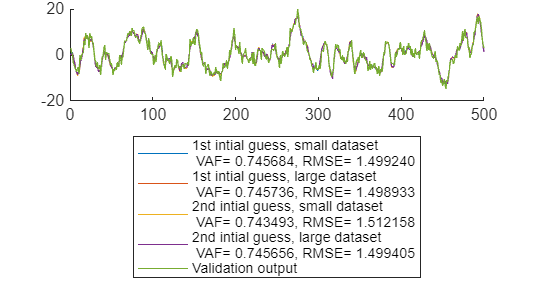


txt_s1s = sprintf("1st intial guess, small dataset\n VAF= %f, RMSE= %f", VAF_s1s, RMSE_s1s);
txt_s1l = sprintf("1st intial guess, large dataset\n VAF= %f, RMSE= %f", VAF_s1l, RMSE_s1l);
txt_s2s = sprintf("2nd intial guess, small dataset\n VAF= %f, RMSE= %f", VAF_s2s, RMSE_s2s);
txt_s2l = sprintf("2nd intial guess, large dataset\n VAF= %f, RMSE= %f", VAF_s2l, RMSE_s2l);


hF = figure;
clf;
hold on
plot(y_s1s)
plot(y_s1l)
plot(y_s2s)
plot(y_s2l)
plot(yv)
legend(txt_s1s, txt_s1l, txt_s2s, txt_s2l, "Validation output", location = "southoutside");
hF.Position(3:4) = [960 540];
hold off 

**e) **According to the result in (d), report the system parameters $a_1$, $a_2$, $a_3$, $a_4$, $b_2$, $b_3$, $b_4$ for the best identified model. Explain how you chose the best model.

*Answer**: *

*The starting points were selected based on trial and error and only this combination yielded convergence, where *$a_1 \approx 1, a_2 \approx 0, -a_1 < a_3 <0, a_4 \approx 0$, these starting points all converged to the same final solution, with getting into a local minima. As no relaxation was applied during the newton method the solution got into an oscillating part in some of the runs. The solution selected finally is the first initial guess trained on the large dataset, as that gives the lowest RMSE out of the four. For this $a_1 = -2.3770, a_2 = 2.0548, a_3 = -0.7654, a_4 = 0.1042, b_2 = 0.9966, b_3 = -0.8053, b_4 = 0.2154$

## Functions

Implement your functions in the templates below. 

*You may implement additional functions for your convenience.*

function [Abar,Bbar,C,D,x0] = theta2matrices(theta)
%%
% Function INPUT
% theta     Parameter vector (vector of size: according to the realization)
%
%
% Function OUTPUT
% Abar      System matrix A (matrix of size n x n)
% Bbar      System matrix B (matrix of size n x m)
% C         System matrix C (matrix of size l x n)
% D         System matrix D (matrix of size l x m)
% x0        Initial state (vector of size n x one)





%%%%%% YOUR CODE HERE %%%%%%
theta_a = theta(1:4);
theta_b = theta(5:7);
theta_x0 = theta(8:11);

Abar=[theta_a(1) 1 0 0;
      theta_a(2) 0 1 0;
      theta_a(3) 0 0 1;
      theta_a(4) 0 0 0];
Bbar=[ 0; theta_b(1); theta_b(2); theta_b(3)];
C=[1 0 0 0];
D=[0];
x0=[theta_x0(1); theta_x0(2); theta_x0(3); theta_x0(4)];
end

function [y, x] = simsystem(A, B, C, D, x0, u)
% Instructions:
% Simulating a linear dynamic system given input u, matrices A,B,C,D ,and
% initial condition x(0)
%
 n = size(A, 1); 
 m = size(B, 2); 
 l = size(C, 1);
 N = size(u, 1); 
%
% Function INPUT
% A system matrix (matrix of size n x n)
% B system matrix (matrix of size n x m)
% C system matrix (matrix of size l x n)
% D system matrix (matrix of size l x m)
% x0 initial state (vector of size n x one)
% u system input (matrix of size N x m)
%
% Function OUTPUT
% x state of system (matrix of size N x n)
% y system output (matrix of size N x l)





%%%%%% YOUR CODE HERE %%%%%%
y = zeros(l, N);
x = zeros(n, N+1);

x(:, 1) = x0;

for i = 1:size(u, 1)
    x(:, i+1) = (A * x(:, i) + B * u(i, :));
    y(:, i) = (C * x(:, i) + D * u(i, :));
end

x = x(:, 1:N)';
y = y';
end

function J = jacobian(psi,E)
% Instructions:
% This function calculates the Jacobian vector in the Gauss-Newton
% algorithm
%
%  p = size(theta); 
%  N = size(y, 1); 
%  l = size(C, 1);
%
% Function INPUT
% psi derivative of estimation error wrt theta (matrix of size l*N x p)
% E estimation error vector (vector of size l*N x one)
%
% Function OUTPUT
% J Jacobian vector (vector of size p x one)





%%%%%% YOUR CODE HERE %%%%%%
N = size(psi, 1);
J = 2/N * psi' * E;
end

function H = hessian(psi)
% Instructions:
% This function calculates the approximated Hessian matrix in the Gauss-Newton
% algorithm
%
%  p = size(theta); 
%  N = size(y, 1); 
%  l = size(C, 1);
%
% Function INPUT
% psi derivative of estimation error wrt theta (matrix of size l*N x p)
%
% Function OUTPUT
% H Hessian matrix (matrix of size p x p)





%%%%%% YOUR CODE HERE %%%%%%
N = size(psi, 1);
H = 2/N * (psi' * psi);
end

function [Abar,Bbar,C,D,x0, J, H] = pem(theta,A0,B0,C0,D0,x00,y,u,lambda,maxiter)
% Instructions:
% Implement your Prediction Error Method for the Output Error system here.
% Use the following function inputs and outputs.
%
% Function INPUT
% theta  Paramter vector (size: depends on your mapping choice)
% A0 Initial guess for system matrix A (matrix of size n x n)
% B0 Initial guess for system matrix B (matrix of size n x m)
% C0 Initial guess for system matrix C (matrix of size l x n)
% D0 Initial guess for system matrix D (matrix of size l x m)
% x00 Initial guess for initial state (vector of size n x one)
% u System input (matrix of size N x m)
% y System output (matrix of size N x l)
% lambda regularization parameter (scalar)
% maxiter Maximum number of iterations (scalar)
%
%
% Function OUTPUT
% Abar Estimate of system matrix A (matrix of size n x n)
% Bbar Estimate of system matrix B (matrix of size n x m)
% C Estimate of system matrix C (matrix of size l x n)
% D Estimate of system matrix D (matrix of size l x m)
% x0 Estimate of initial state (vector of size n x one)





%%%%%% YOUR CODE HERE %%%%%%
% check the given inputs for consistency
[A, B, C, D, x0] = theta2matrices(theta);
assert(isequal(A, A0))
assert(isequal(B, B0))
assert(isequal(C, C0))
assert(isequal(D, D0))
assert(isequal(x0, x00))
% traj = simsystem(A, B, C, D, x0);


p = size(theta, 1);
N = size(y, 1);
n = size(A, 1);


% Gauss-Newton

% initialize
converged = false;
maxiter_reached = false;
iter = 1;
e_hist = [];
while ~converged && ~maxiter_reached
    [A, B, C, D, x0] = theta2matrices(theta);
    [y_sim, x_sim] = simsystem(A, B, C, D, x0, u);
    E = y-y_sim;
    e_hist = cat(1, e_hist, norm(E));
    psi = setup_psi(A, C, x_sim, u);
    jaco = jacobian(psi, E);
    hess = hessian(psi);
    % size(jaco)
    % size(theta)
    % size(theta - inv(hess + lambda * eye(p)) * jaco)
    % size(inv(hess + lambda * eye(p)) * jaco)
    theta_new = theta + (hess + lambda * eye(p)) \ jaco;
    % theta_new'
    if anynan(psi)
        % psi
        disp('nans in psi')
        break
    end
    if anynan(theta_new)
        disp('nans in theta:')
        % theta_new
        % psi
        % hess
        % A
        % (hess + lambda * eye(p))
        break
    end
    % Check convergence
    if norm(theta_new - theta) < 1e-3 
        converged = true; 
    elseif iter == maxiter 
        maxiter_reached = true; 
        warning('Maximum iterations reached'); 
    end
    theta = theta_new; 
    iter = iter + 1;
end
e_hist';
theta;

%%%%%% YOUR CODE HERE %%%%%%
[Abar, Bbar, C, D, x0] = theta2matrices(theta);
J = jaco;
H = hess;
     
end

function [psi] = setup_psi(A, C, x, u)
    N = size(x, 1);
    p = 11;
    n = 4;

    psi = zeros(N, p);
    dA_dtheta = zeros(n, n, p);
    dA_dtheta(1:4, 1, 1:4) = eye(4);
    
    dB_dtheta = zeros(n, 1, p);
    dB_dtheta(2:4, 5:7) = eye(3);
    
    dx0_dtheta = zeros(n, 1, p);
    dx0_dtheta(:, 1, 8:11) = eye(4);

    for p = 1:4
        dx_dtheta = dx0_dtheta(:, 1, p);
        for j = 1:N
            psi(j, p) = C * dx_dtheta;
            p1 = A * dx_dtheta;
            p2 = dA_dtheta(:, :, p) * x(j, :)';
            dx_dtheta = p1 + p2;
            if anynan(psi)
                disp('nans in A part {i}')
            end
        end
    end
    for p = 5:7
        dx_dtheta = dx0_dtheta(:, 1, p);
        for j = 1:N
            psi(j, p) = C * dx_dtheta;
            p1 = A * dx_dtheta;
            p3 = dB_dtheta(:, :, p)*u(j);
            dx_dtheta = p1 +p3;
        end
        if anynan(psi)
            disp('nans in B part {i}')
        end
    end
    for p = 8:11
        dx_dtheta = dx0_dtheta(:, 1, p);
        for j = 1:N
            psi(j, p) = C * dx_dtheta;
            p1 = A * dx_dtheta;
            dx_dtheta = p1;
        end
        if anynan(psi)
            disp('nans in x0 part {i}')
            dx0_dtheta(:, 1, p)
            A
        end
    end
end
